# Ejercicio 2.5

 **a) **

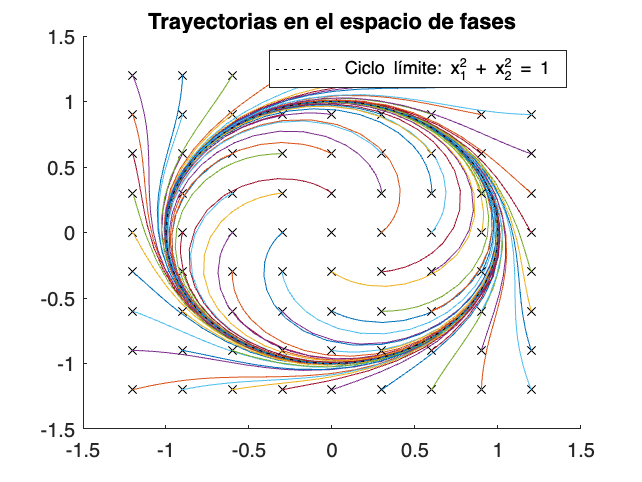

tspan = [0, -10];
x0 = [-1.2:0.3:1.2];

hold on;
for i = 1:length(x0)
    for j = 1:length(x0)
        [ti, xi] = ode45(@(t,x)sistema(t,x), tspan, [x0(i), x0(j)]');
        %Miedo me dan todas las advertencias que saltan pero creo que están
        %relacionadas con el ciclo límite.
        plot(x0(i), x0(j), "xk");
        plot(xi(:,1), xi(:,2));
    end
end

xc = [-1:0.01:1];
cp = plot(xc, (1-xc.^2).^.5, ":k"); %parte positiva de la circunferencia límite
cn = plot(xc, -(1-xc.^2).^.5, ":k"); %parte negativa
legend(cp, "Ciclo límite: x_1^2 + x_2^2 = 1")
title("Trayectorias en el espacio de fases")
xlim([-1.5, 1.5]);
ylim([-1.5, 1.5]);
hold off;

**b)**

function xdot = sistema(t, x)
    
    xdot(1,1) = -x(1,1) * (1 - x(1,1)^2 - x(2,1)^2) + x(2,1);
    xdot(2,1) = -x(2,1) * (1 - x(1,1)^2 - x(2,1)^2) - x(1,1);

end